% Specify the filename
filename = '/home/rachel/Downloads/2024-06-30T16/2024-06-30T16/2024-06-30T16-b9stim.h5';  % Replace with your actual file name

% Display the structure of the HDF5 file
h5disp(filename);

HDF5 2024-06-30T16-b9stim.h5 
Group '/' 
    Attributes:
        'McsHdf5ProtocolType':  'RawData'
        'McsHdf5ProtocolVersion':  3
        'McsDataToolsVersion':  '1.7.1.15'
        'GeneratingApplicationName':  'Multi Channel DataManager'
        'GeneratingApplicationVersion':  '1.14.10.23023'
    Group '/Data' 
        Attributes:
            'ProgramName':  'Multi Channel Experimenter'
            'ProgramVersion':  '2.20.7.23178'
            'MeaName':  'ME21Combi120'
            'MeaLayout':  'ME21Combi120'
            'MeaSN':  ''
            'Date':  'Sunday, June 30, 2024'
            'DateInTicks':  638553614286375873
            'FileGUID':  'bfd1234b-2f0b-4ed4-943a-7753fd44adc9'
            'Comment':  ''
        Group '/Data/Recording_0' 
            Attributes:
                'RecordingID':  0
                'RecordingType':  ''
                'TimeStamp':  0
                'Duration':  60200000
                'Label':  ''
                'Comment':  ''
        

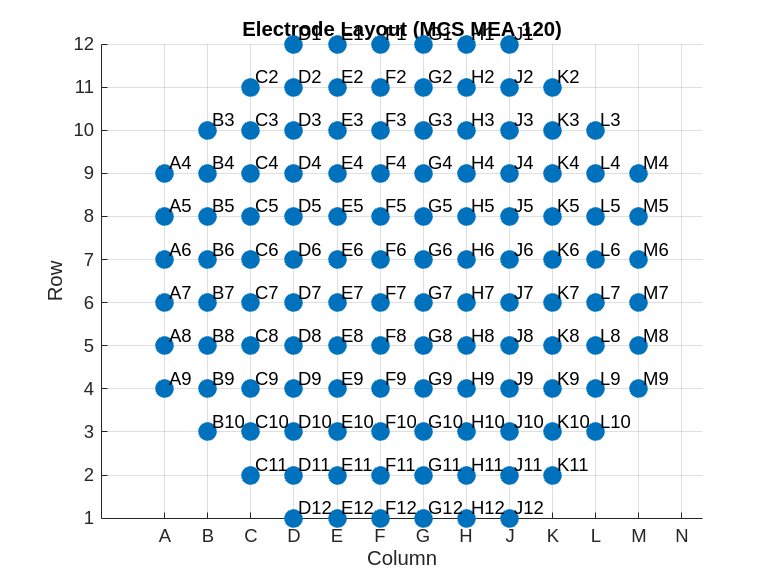

% Define the dataset path for InfoChannel
infoPath = '/Data/Recording_0/AnalogStream/Stream_0/InfoChannel';

% Read the InfoChannel dataset
infoChannel = h5read(filename, infoPath);

% Extract the Channel IDs from the InfoChannel dataset
channelIDs = infoChannel.ChannelID;  % Hardware IDs from data (zero-based indexing)

% Adjust channelIDs to one-based indexing
channelIDs_one_based = channelIDs + 1;

% Define the hardware IDs and corresponding electrode IDs (one-based indexing)
hw_ids = [
    % First column from your table
    60, 59, 58, 57, 56, 55, 54, 53, 52, 51, 50, 49, 48, 47, 46, 45, 44, 43, 42, 41, 40, 39, 38, 37, 36, 35, 34, 33, 32, 31, ...
    % Second column
    120, 119, 118, 117, 116, 115, 114, 113, 112, 111, 110, 109, 108, 107, 106, 105, 104, 103, 102, 101, 100, 99, 98, 97, 96, 95, 94, 93, 92, 91, ...
    % Third column
    90, 89, 88, 87, 86, 85, 84, 83, 82, 81, 80, 79, 78, 77, 76, 75, 74, 73, 72, 71, 70, 69, 68, 67, 66, 65, 64, 63, 62, 61, ...
    % Fourth column
    30, 29, 28, 27, 26, 25, 24, 23, 22, 21, 20, 19, 18, 17, 16, 15, 14, 13, 12, 11, 10, 9, 8, 7, 6, 5, 4, 3, 2, 1
];

el_ids = {
    % First column EL IDs
    'F5', 'F1', 'F2', 'F3', 'F4', 'E1', 'E2', 'E3', 'E4', 'D1', 'D2', 'D3', 'E5', 'C2', 'C3', 'B3', 'D4', 'C4', 'B4', 'A4', 'D5', 'C5', 'B5', 'A5', 'D6', 'C6', 'B6', 'A6', 'E6', 'F6', ...
    % Second column EL IDs
    'G8', 'G12', 'G11', 'G10', 'G9', 'H12', 'H11', 'H10', 'H9', 'J12', 'J11', 'J10', 'H8', 'K11', 'K10', 'L10', 'J9', 'K9', 'L9', 'M9', 'J8', 'K8', 'L8', 'M8', 'J7', 'K7', 'L7', 'M7', 'H7', 'G7', ...
    % Third column EL IDs
    'H6', 'M6', 'L6', 'K6', 'J6', 'M5', 'L5', 'K5', 'J5', 'M4', 'L4', 'K4', 'H5', 'L3', 'K3', 'K2', 'J4', 'J3', 'J2', 'J1', 'H4', 'H3', 'H2', 'H1', 'G4', 'G3', 'G2', 'G1', 'G5', 'G6', ...
    % Fourth column EL IDs
    'E7', 'A7', 'B7', 'C7', 'D7', 'A8', 'B8', 'C8', 'D8', 'A9', 'B9', 'C9', 'E8', 'B10', 'C10', 'C11', 'D9', 'D10', 'D11', 'D12', 'E9', 'E10', 'E11', 'E12', 'F9', 'F10', 'F11', 'F12', 'F8', 'F7'
};

% Create a mapping between hardware IDs and electrode IDs 
hw_to_el_map = containers.Map(hw_ids, el_ids);

% Get the electrode names for the channels 
numChannels = length(channelIDs_one_based);
electrodeNames = cell(numChannels, 1);

for i = 1:numChannels
    hw_id = channelIDs_one_based(i);  % Hardware IDs adjusted to one-based indexing
    if isKey(hw_to_el_map, hw_id)
        electrodeNames{i} = hw_to_el_map(hw_id);
    else
        electrodeNames{i} = 'Unknown';
        warning(['Hardware ID ', num2str(hw_id), ' not found in mapping.']);
    end
end

% Initialize arrays to hold grid positions
X = zeros(numChannels, 1);  % Column indices
Y = zeros(numChannels, 1);  % Row indices

% Define the list of column letters in order
columnLetters = {'A', 'B', 'C', 'D', 'E', 'F', 'G', 'H', 'J', 'K', 'L', 'M', 'N', 'O', 'P'}; % can be adjusted for other MEAs
numColumns = length(columnLetters);
columnMap = containers.Map(columnLetters, 1:numColumns);
maxRowNumber = 12; 

for i = 1:numChannels
    electrode = electrodeNames{i};
    if strcmp(electrode, 'Unknown')
        % Skip unknown electrodes
        X(i) = NaN;
        Y(i) = NaN;
        continue;
    end
    % Find the index where the digits start
    idx = regexp(electrode, '\d');
    if isempty(idx)
        error(['No digits found in electrode name: ', electrode]);
    end
    colStr = electrode(1:idx(1)-1);  % Column letters
    rowStr = electrode(idx(1):end);  % Row number as string

    % Map column letters to numerical positions
    if isKey(columnMap, colStr)
        colNum = columnMap(colStr);
    else
        error(['Column letter ', colStr, ' not found in column mapping.']);
    end

    % Convert row string to numerical value
    rowNum = str2double(rowStr);
    if isnan(rowNum)
        error(['Invalid row number in electrode name: ', electrode]);
    end

    % Store the positions
    X(i) = colNum;
    Y(i) = rowNum;
end

% Adjust Y positions if necessary (e.g., flip Y-axis)
Y = maxRowNumber - Y + 1;

% Remove any electrodes with unknown positions
validIndices = ~isnan(X) & ~isnan(Y);
X_valid = X(validIndices);
Y_valid = Y(validIndices);
electrodeNames_valid = electrodeNames(validIndices);

% Create a scatter plot of the electrode positions
figure;
scatter(X_valid, Y_valid, 100, 'filled');
text(X_valid + 0.1, Y_valid, electrodeNames_valid, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
xlabel('Column');
ylabel('Row');
title('Electrode Layout (MCS MEA 120)');
axis equal;
set(gca, 'YDir', 'normal');  % Adjust to 'reverse' if necessary
xticks(1:numColumns);
xticklabels(columnLetters);
yticks(1:maxRowNumber);
grid on;

% Print the first few positions to verify it's correct
for i = 1:min(5, length(X_valid))
    fprintf('Electrode %s: Column = %d, Row = %d\n', electrodeNames_valid{i}, X_valid(i), Y_valid(i));
end

Electrode F7: Column = 6, Row = 6
Electrode F8: Column = 6, Row = 5
Electrode F12: Column = 6, Row = 1
Electrode F11: Column = 6, Row = 2
Electrode F10: Column = 6, Row = 3


% Define the dataset paths for Stream 0 (filtered data)
dataPath = '/Data/Recording_0/AnalogStream/Stream_0/ChannelData';
infoPath = '/Data/Recording_0/AnalogStream/Stream_0/InfoChannel';
data = h5read(filename, dataPath);
numChannels = length(infoChannel.ChannelID);

% Extract conversion factors, exponents, and ADZero values
conversionFactors = double(infoChannel.ConversionFactor);
exponents = double(infoChannel.Exponent);
ADZero = double(infoChannel.ADZero);

% Initialize the converted data matrix
data_in_uV = zeros(size(data), 'double');

% Perform the conversion for each channel
for ch = 1:numChannels
    % Convert raw data to microvolts using the formula:
    % data_in_uV = (data - ADZero) * ConversionFactor * 10^Exponent
    data_in_uV(:, ch) = (double(data(:, ch)) - ADZero(ch)) * conversionFactors(ch) * 10^(exponents(ch));
end

fs = 20000;  % Sampling rate in Hz 

% High-pass filter settings
hpOrder = 2;
hpCutoff = 300;  % High-pass cutoff frequency in Hz

% Low-pass filter settings
lpOrder = 2;
lpCutoff = 3500;  % Low-pass cutoff frequency in Hz

% Design the high-pass filter
highPassFilt = designfilt('highpassiir', 'FilterOrder', hpOrder, ...
    'HalfPowerFrequency', hpCutoff, 'SampleRate', fs);

% Design the low-pass filter
lowPassFilt = designfilt('lowpassiir', 'FilterOrder', lpOrder, ...
    'HalfPowerFrequency', lpCutoff, 'SampleRate', fs);

% Design the notch filters (used in Gianna's code)
notchFilt = designfilt('bandstopiir', 'FilterOrder', 2, ...
    'HalfPowerFrequency1', 58, 'HalfPowerFrequency2', 62, 'SampleRate', fs);

lightFilt = designfilt('bandstopiir', 'FilterOrder', 2, ...
    'HalfPowerFrequency1', 175, 'HalfPowerFrequency2', 180, 'SampleRate', fs);

noiseFilt1 = designfilt('bandstopiir', 'FilterOrder', 2, ...
    'HalfPowerFrequency1', 780, 'HalfPowerFrequency2', 782, 'SampleRate', fs);

noiseFilt2 = designfilt('bandstopiir', 'FilterOrder', 2, ...
    'HalfPowerFrequency1', 1561, 'HalfPowerFrequency2', 1563, 'SampleRate', fs);

noiseFilt3 = designfilt('bandstopiir', 'FilterOrder', 2, ...
    'HalfPowerFrequency1', 2159, 'HalfPowerFrequency2', 2161, 'SampleRate', fs);

noiseFilt4 = designfilt('bandstopiir', 'FilterOrder', 2, ...
    'HalfPowerFrequency1', 3124, 'HalfPowerFrequency2', 3126, 'SampleRate', fs);

% Initialize the filtered data matrix
filteredData = data_in_uV;

% Apply the high-pass filter
for ch = 1:numChannels
    filteredData(:, ch) = filtfilt(highPassFilt, filteredData(:, ch));
end

% Apply the low-pass filter
for ch = 1:numChannels
    filteredData(:, ch) = filtfilt(lowPassFilt, filteredData(:, ch));
end

% Apply the notch filters in sequence
for ch = 1:numChannels
    % Apply 60 Hz notch filter
    filteredData(:, ch) = filtfilt(notchFilt, filteredData(:, ch));
    % Apply light interference filter
    filteredData(:, ch) = filtfilt(lightFilt, filteredData(:, ch));
    % Apply additional noise filters
    filteredData(:, ch) = filtfilt(noiseFilt1, filteredData(:, ch));
    filteredData(:, ch) = filtfilt(noiseFilt2, filteredData(:, ch));
    filteredData(:, ch) = filtfilt(noiseFilt3, filteredData(:, ch));
    filteredData(:, ch) = filtfilt(noiseFilt4, filteredData(:, ch));
end

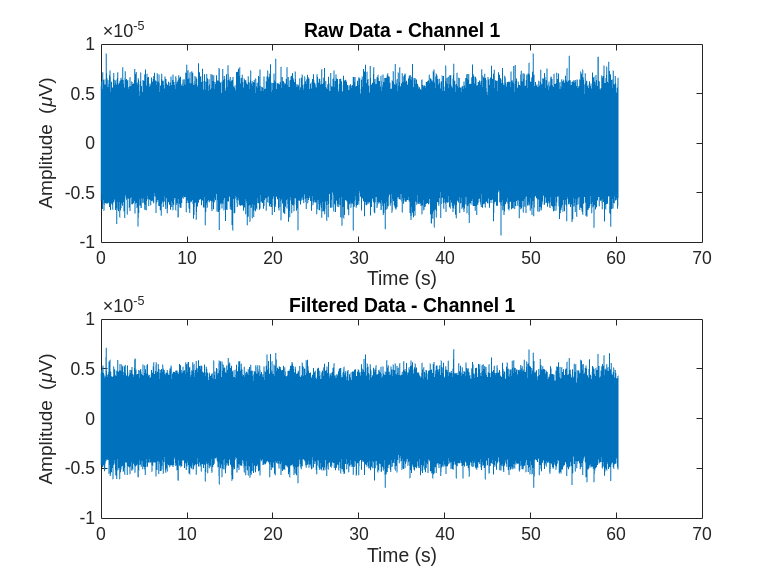

% Select a channel to visualize
channelIdx = 1;  % Change as needed

% Time vector for plotting
totalSamples = size(filteredData, 1);
timeVector = (0:totalSamples - 1) / fs;

% Plot raw vs. filtered data
figure;
subplot(2, 1, 1);
plot(timeVector, data_in_uV(:, channelIdx));
xlabel('Time (s)');
ylabel('Amplitude (\muV)');
title(['Raw Data - Channel ' num2str(channelIdx)]);

subplot(2, 1, 2);
plot(timeVector, filteredData(:, channelIdx));
xlabel('Time (s)');
ylabel('Amplitude (\muV)');
title(['Filtered Data - Channel ' num2str(channelIdx)]);

% Spike detection parameters
thresholdMultiplier = 5;     % Multiplier for noise standard deviation
deadTime = 0.003;            % Refractory period in seconds (3 ms)
windowMs = 300;              % Window size in milliseconds for noise estimation
numSegments = 3;             % Number of segments for noise estimation
preEventMs = 1;              % Time before spike in ms
postEventMs = 2;             % Time after spike in ms

% Convert window size and pre/post-event times to samples
windowSamples = round(windowMs / 1000 * fs);
preEventSamples = round(preEventMs / 1000 * fs);
postEventSamples = round(postEventMs / 1000 * fs);

% Initialize cell arrays to store spike times, waveforms, and polarities
spikeTimes = cell(numChannels, 1);
spikeWaveforms = cell(numChannels, 1);
spikePolarities = cell(numChannels, 1);

% Total number of samples
totalSamples = size(filteredData, 1);

% Loop over each channel
for ch = 1:numChannels
    % Get the data for this channel
    channelData = filteredData(:, ch);
    
    % Get the hardware ID for this channel and adjust to be one-based
    hw_id = infoChannel.ChannelID(ch) + 1;  % Adjusted to be one-based

    % Use the mapping to get the electrode label
    if isKey(hw_to_el_map, hw_id)
        electrodeLabel = hw_to_el_map(hw_id);
    else
        electrodeLabel = 'Unknown';
    end

   
    % -------- Noise Estimation --------
    % Estimate noise level using segments of the data
    % Estimate noise level using segments of the data
    segmentLength = windowSamples;  % Length of each segment
    segmentStarts = round(linspace(1, totalSamples - segmentLength, numSegments));
    noiseStds = zeros(numSegments, 1);  % To store noise stds from each segment
    
    fprintf('Noise estimation segments for Channel %d (Electrode %s):\n', ch, electrodeLabel);
    
    for s = 1:numSegments
        % Ensure that the segment does not exceed the data length
        startIdx = segmentStarts(s);
        endIdx = min(segmentStarts(s) + segmentLength - 1, totalSamples);
        
        % Debugging: print the start and end of each segment
        fprintf('  Segment %d: Start = %d, End = %d\n', s, startIdx, endIdx);
        
        % Extract the segment
        segment = channelData(startIdx:endIdx);
        
        % Calculate the standard deviation of the segment (assuming it's noise)
        noiseStds(s) = std(segment);
    end
    
    % Debugging: print the stds for each segment
    fprintf('  Noise stds for each segment: ');
    disp(noiseStds);
    
    % Average the standard deviations from each segment to get the overall noise level
    noiseStd = mean(noiseStds);
    
    % Debugging: print the final estimated noise std for this channel
    fprintf('Estimated noise std for Channel %d (Electrode %s): %.10f\n', ch, electrodeLabel, noiseStd);


    % -------- End Noise Estimation --------

    % Set thresholds for positive and negative spikes
    positiveThreshold = thresholdMultiplier * noiseStd;
    negativeThreshold = -thresholdMultiplier * noiseStd;

    % Detect positive threshold crossings
    positiveSpikeIndices = find(channelData > positiveThreshold);

    % Detect negative threshold crossings
    negativeSpikeIndices = find(channelData < negativeThreshold);

    % Combine and sort spike indices
    allSpikeIndices = sort([positiveSpikeIndices; negativeSpikeIndices]);

    % Determine spike polarities
    allSpikePolarities = zeros(length(allSpikeIndices), 1);
    allSpikePolarities(ismember(allSpikeIndices, positiveSpikeIndices)) = 1;   % Positive spikes
    allSpikePolarities(ismember(allSpikeIndices, negativeSpikeIndices)) = -1;  % Negative spikes

    % Enforce dead time (refractory period)
    deadTimeSamples = round(deadTime * fs);
    numSpikesDetected = length(allSpikeIndices);

    if numSpikesDetected > 0
        % Compute differences between spike indices
        spikeDiffs = diff(allSpikeIndices);
        
        % Determine which spikes to keep
        keepSpikes = [true; spikeDiffs > deadTimeSamples];
        
        % Ensure keepSpikes has the same length as allSpikeIndices
        keepSpikes = keepSpikes(1:numSpikesDetected);
        
        % Apply the logical indexing
        spikeIndices = allSpikeIndices(keepSpikes);
        spikePolarities_ch = allSpikePolarities(keepSpikes);
    else
        % No spikes detected
        spikeIndices = [];
        spikePolarities_ch = [];
    end

    % Extract spike times in seconds
    spikeTimes{ch} = spikeIndices / fs;

    % Extract spike waveforms
    numSpikes = length(spikeIndices);
    if numSpikes > 0
        waveforms = zeros(numSpikes, preEventSamples + postEventSamples + 1);
        for i = 1:numSpikes
            idx = spikeIndices(i);
            if idx - preEventSamples > 0 && idx + postEventSamples <= totalSamples
                waveforms(i, :) = channelData(idx - preEventSamples : idx + postEventSamples);
            else
                waveforms(i, :) = NaN;
            end
        end
        spikeWaveforms{ch} = waveforms;
        spikePolarities{ch} = spikePolarities_ch;
    else
        spikeWaveforms{ch} = [];
        spikePolarities{ch} = [];
    end

    % Calculate firing rate
    recordingDuration = totalSamples / fs;
    firingRate = numSpikes / recordingDuration; % Spikes per second

    % Display the number of spikes detected with correct electrode labels
    if numSpikes > 0
    fprintf('Channel %d (HW ID %d, %s): %d spikes detected, firing rate = %.2f Hz\n', ...
        ch, hw_id, electrodeLabel, numSpikes, firingRate);
    end
end

Noise estimation segments for Channel 1 (Electrode F7):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1484
    0.1431
    0.1450



Estimated noise std for Channel 1 (Electrode F7): 0.0000014551


Noise estimation segments for Channel 2 (Electrode F8):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.6947
    0.7600
    0.7533



Estimated noise std for Channel 2 (Electrode F8): 0.0000073601


Channel 2 (HW ID 2, F8): 10 spikes detected, firing rate = 0.17 Hz


Noise estimation segments for Channel 3 (Electrode F12):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1423
    0.1413
    0.1470



Estimated noise std for Channel 3 (Electrode F12): 0.0000014353


Channel 3 (HW ID 3, F12): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 4 (Electrode F11):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1395
    0.1391
    0.1457



Estimated noise std for Channel 4 (Electrode F11): 0.0000014142


Noise estimation segments for Channel 5 (Electrode F10):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1486
    0.1482
    0.1434



Estimated noise std for Channel 5 (Electrode F10): 0.0000014672


Noise estimation segments for Channel 6 (Electrode F9):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1468
    0.1487
    0.1446



Estimated noise std for Channel 6 (Electrode F9): 0.0000014667


Noise estimation segments for Channel 7 (Electrode E12):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1447
    0.1510
    0.1452



Estimated noise std for Channel 7 (Electrode E12): 0.0000014694


Noise estimation segments for Channel 8 (Electrode E11):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1451
    0.1465
    0.1458



Estimated noise std for Channel 8 (Electrode E11): 0.0000014581


Noise estimation segments for Channel 9 (Electrode E10):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1466
    0.1458
    0.1438



Estimated noise std for Channel 9 (Electrode E10): 0.0000014541


Channel 9 (HW ID 9, E10): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 10 (Electrode E9):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1464
    0.1513
    0.1439



Estimated noise std for Channel 10 (Electrode E9): 0.0000014718


Noise estimation segments for Channel 11 (Electrode D12):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1472
    0.1423
    0.1448



Estimated noise std for Channel 11 (Electrode D12): 0.0000014476


Noise estimation segments for Channel 12 (Electrode D11):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1395
    0.1370
    0.1390



Estimated noise std for Channel 12 (Electrode D11): 0.0000013849


Channel 12 (HW ID 12, D11): 2 spikes detected, firing rate = 0.03 Hz


Noise estimation segments for Channel 13 (Electrode D10):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1488
    0.1503
    0.1495



Estimated noise std for Channel 13 (Electrode D10): 0.0000014954


Noise estimation segments for Channel 14 (Electrode D9):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1331
    0.1373
    0.1402



Estimated noise std for Channel 14 (Electrode D9): 0.0000013683


Noise estimation segments for Channel 15 (Electrode C11):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1416
    0.1424
    0.1475



Estimated noise std for Channel 15 (Electrode C11): 0.0000014384


Channel 15 (HW ID 15, C11): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 16 (Electrode C10):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1454
    0.1408
    0.1432



Estimated noise std for Channel 16 (Electrode C10): 0.0000014314


Noise estimation segments for Channel 17 (Electrode B10):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.2630
    0.2531
    0.2728



Estimated noise std for Channel 17 (Electrode B10): 0.0000026294


Channel 17 (HW ID 17, B10): 167 spikes detected, firing rate = 2.77 Hz


Noise estimation segments for Channel 18 (Electrode E8):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1456
    0.1471
    0.1458



Estimated noise std for Channel 18 (Electrode E8): 0.0000014618


Noise estimation segments for Channel 19 (Electrode C9):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1422
    0.1527
    0.1487



Estimated noise std for Channel 19 (Electrode C9): 0.0000014784


Channel 19 (HW ID 19, C9): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 20 (Electrode B9):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.2497
    0.2447
    0.2433



Estimated noise std for Channel 20 (Electrode B9): 0.0000024591


Channel 20 (HW ID 20, B9): 105 spikes detected, firing rate = 1.74 Hz


Noise estimation segments for Channel 21 (Electrode A9):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1439
    0.1493
    0.1482



Estimated noise std for Channel 21 (Electrode A9): 0.0000014712


Channel 21 (HW ID 21, A9): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 22 (Electrode D8):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1954
    0.2001
    0.1973



Estimated noise std for Channel 22 (Electrode D8): 0.0000019759


Noise estimation segments for Channel 23 (Electrode C8):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1866
    0.1849
    0.1976



Estimated noise std for Channel 23 (Electrode C8): 0.0000018969


Channel 23 (HW ID 23, C8): 66 spikes detected, firing rate = 1.10 Hz


Noise estimation segments for Channel 24 (Electrode B8):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1499
    0.1502
    0.1532



Estimated noise std for Channel 24 (Electrode B8): 0.0000015112


Channel 24 (HW ID 24, B8): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 25 (Electrode A8):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1450
    0.1464
    0.1428



Estimated noise std for Channel 25 (Electrode A8): 0.0000014473


Noise estimation segments for Channel 26 (Electrode D7):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1528
    0.1536
    0.1560



Estimated noise std for Channel 26 (Electrode D7): 0.0000015416


Noise estimation segments for Channel 27 (Electrode C7):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1477
    0.1516
    0.1568



Estimated noise std for Channel 27 (Electrode C7): 0.0000015206


Channel 27 (HW ID 27, C7): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 28 (Electrode B7):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1949
    0.1992
    0.2048



Estimated noise std for Channel 28 (Electrode B7): 0.0000019965


Noise estimation segments for Channel 29 (Electrode A7):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.2567
    0.2708
    0.2706



Estimated noise std for Channel 29 (Electrode A7): 0.0000026605


Channel 29 (HW ID 29, A7): 2 spikes detected, firing rate = 0.03 Hz


Noise estimation segments for Channel 30 (Electrode E7):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.2759
    0.2732
    0.2678



Estimated noise std for Channel 30 (Electrode E7): 0.0000027230


Noise estimation segments for Channel 31 (Electrode F6):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.2735
    0.2867
    0.2754



Estimated noise std for Channel 31 (Electrode F6): 0.0000027853


Channel 31 (HW ID 31, F6): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 32 (Electrode E6):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.2667
    0.2658
    0.2733



Estimated noise std for Channel 32 (Electrode E6): 0.0000026859


Channel 32 (HW ID 32, E6): 2 spikes detected, firing rate = 0.03 Hz


Noise estimation segments for Channel 33 (Electrode A6):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1744
    0.1691
    0.1692



Estimated noise std for Channel 33 (Electrode A6): 0.0000017089


Noise estimation segments for Channel 34 (Electrode B6):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1481
    0.1510
    0.1467



Estimated noise std for Channel 34 (Electrode B6): 0.0000014861


Channel 34 (HW ID 34, B6): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 35 (Electrode C6):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1481
    0.1423
    0.1428



Estimated noise std for Channel 35 (Electrode C6): 0.0000014439


Channel 35 (HW ID 35, C6): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 36 (Electrode D6):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1505
    0.1471
    0.1457



Estimated noise std for Channel 36 (Electrode D6): 0.0000014777


Channel 36 (HW ID 36, D6): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 37 (Electrode A5):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1506
    0.1535
    0.1568



Estimated noise std for Channel 37 (Electrode A5): 0.0000015363


Noise estimation segments for Channel 38 (Electrode B5):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1461
    0.1480
    0.1447



Estimated noise std for Channel 38 (Electrode B5): 0.0000014628


Channel 38 (HW ID 38, B5): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 39 (Electrode C5):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1494
    0.1469
    0.1507



Estimated noise std for Channel 39 (Electrode C5): 0.0000014899


Channel 39 (HW ID 39, C5): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 40 (Electrode D5):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1430
    0.1490
    0.1541



Estimated noise std for Channel 40 (Electrode D5): 0.0000014867


Noise estimation segments for Channel 41 (Electrode A4):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1497
    0.1503
    0.1520



Estimated noise std for Channel 41 (Electrode A4): 0.0000015065


Channel 41 (HW ID 41, A4): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 42 (Electrode B4):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1459
    0.1481
    0.1469



Estimated noise std for Channel 42 (Electrode B4): 0.0000014697


Noise estimation segments for Channel 43 (Electrode C4):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1476
    0.1511
    0.1490



Estimated noise std for Channel 43 (Electrode C4): 0.0000014922


Noise estimation segments for Channel 44 (Electrode D4):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1452
    0.1509
    0.1537



Estimated noise std for Channel 44 (Electrode D4): 0.0000014993


Noise estimation segments for Channel 45 (Electrode B3):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1511
    0.1604
    0.1536



Estimated noise std for Channel 45 (Electrode B3): 0.0000015502


Noise estimation segments for Channel 46 (Electrode C3):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1436
    0.1512
    0.1513



Estimated noise std for Channel 46 (Electrode C3): 0.0000014871


Channel 46 (HW ID 46, C3): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 47 (Electrode C2):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1497
    0.1446
    0.1432



Estimated noise std for Channel 47 (Electrode C2): 0.0000014586


Noise estimation segments for Channel 48 (Electrode E5):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1412
    0.1466
    0.1448



Estimated noise std for Channel 48 (Electrode E5): 0.0000014420


Noise estimation segments for Channel 49 (Electrode D3):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1494
    0.1474
    0.1516



Estimated noise std for Channel 49 (Electrode D3): 0.0000014944


Noise estimation segments for Channel 50 (Electrode D2):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1465
    0.1436
    0.1447



Estimated noise std for Channel 50 (Electrode D2): 0.0000014493


Channel 50 (HW ID 50, D2): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 51 (Electrode D1):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1615
    0.1569
    0.1563



Estimated noise std for Channel 51 (Electrode D1): 0.0000015824


Noise estimation segments for Channel 52 (Electrode E4):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1438
    0.1440
    0.1460



Estimated noise std for Channel 52 (Electrode E4): 0.0000014461


Channel 52 (HW ID 52, E4): 2 spikes detected, firing rate = 0.03 Hz


Noise estimation segments for Channel 53 (Electrode E3):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1510
    0.1447
    0.1523



Estimated noise std for Channel 53 (Electrode E3): 0.0000014932


Channel 53 (HW ID 53, E3): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 54 (Electrode E2):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1457
    0.1465
    0.1453



Estimated noise std for Channel 54 (Electrode E2): 0.0000014582


Channel 54 (HW ID 54, E2): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 55 (Electrode E1):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1503
    0.1533
    0.1497



Estimated noise std for Channel 55 (Electrode E1): 0.0000015109


Channel 55 (HW ID 55, E1): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 56 (Electrode F4):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1474
    0.1492
    0.1494



Estimated noise std for Channel 56 (Electrode F4): 0.0000014866


Channel 56 (HW ID 56, F4): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 57 (Electrode F3):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1466
    0.1443
    0.1468



Estimated noise std for Channel 57 (Electrode F3): 0.0000014589


Channel 57 (HW ID 57, F3): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 58 (Electrode F2):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1517
    0.1589
    0.1557



Estimated noise std for Channel 58 (Electrode F2): 0.0000015543


Noise estimation segments for Channel 59 (Electrode F1):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.3145
    0.3274
    0.3146



Estimated noise std for Channel 59 (Electrode F1): 0.0000031885


Noise estimation segments for Channel 60 (Electrode F5):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.3428
    0.3546
    0.3526



Estimated noise std for Channel 60 (Electrode F5): 0.0000034999


Noise estimation segments for Channel 61 (Electrode G6):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.3144
    0.3259
    0.3229



Estimated noise std for Channel 61 (Electrode G6): 0.0000032109


Channel 61 (HW ID 61, G6): 2 spikes detected, firing rate = 0.03 Hz


Noise estimation segments for Channel 62 (Electrode G5):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1930
    0.1982
    0.2048



Estimated noise std for Channel 62 (Electrode G5): 0.0000019869


Noise estimation segments for Channel 63 (Electrode G1):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1606
    0.1611
    0.1572



Estimated noise std for Channel 63 (Electrode G1): 0.0000015964


Noise estimation segments for Channel 64 (Electrode G2):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1517
    0.1500
    0.1489



Estimated noise std for Channel 64 (Electrode G2): 0.0000015019


Noise estimation segments for Channel 65 (Electrode G3):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1458
    0.1448
    0.1413



Estimated noise std for Channel 65 (Electrode G3): 0.0000014400


Noise estimation segments for Channel 66 (Electrode G4):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1486
    0.1435
    0.1415



Estimated noise std for Channel 66 (Electrode G4): 0.0000014452


Noise estimation segments for Channel 67 (Electrode H1):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1516
    0.1507
    0.1502



Estimated noise std for Channel 67 (Electrode H1): 0.0000015085


Channel 67 (HW ID 67, H1): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 68 (Electrode H2):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1493
    0.1479
    0.1448



Estimated noise std for Channel 68 (Electrode H2): 0.0000014732


Channel 68 (HW ID 68, H2): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 69 (Electrode H3):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1453
    0.1431
    0.1426



Estimated noise std for Channel 69 (Electrode H3): 0.0000014367


Channel 69 (HW ID 69, H3): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 70 (Electrode H4):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.8324
    0.8823
    0.8627



Estimated noise std for Channel 70 (Electrode H4): 0.0000085913


Channel 70 (HW ID 70, H4): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 71 (Electrode J1):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.7768
    0.7988
    0.6195



Estimated noise std for Channel 71 (Electrode J1): 0.0000073171


Channel 71 (HW ID 71, J1): 6 spikes detected, firing rate = 0.10 Hz


Noise estimation segments for Channel 72 (Electrode J2):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1470
    0.1499
    0.1470



Estimated noise std for Channel 72 (Electrode J2): 0.0000014796


Noise estimation segments for Channel 73 (Electrode J3):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1455
    0.1416
    0.1419



Estimated noise std for Channel 73 (Electrode J3): 0.0000014298


Noise estimation segments for Channel 74 (Electrode J4):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1378
    0.1429
    0.1428



Estimated noise std for Channel 74 (Electrode J4): 0.0000014115


Noise estimation segments for Channel 75 (Electrode K2):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1539
    0.1507
    0.1533



Estimated noise std for Channel 75 (Electrode K2): 0.0000015266


Noise estimation segments for Channel 76 (Electrode K3):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1442
    0.1441
    0.1451



Estimated noise std for Channel 76 (Electrode K3): 0.0000014448


Noise estimation segments for Channel 77 (Electrode L3):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1457
    0.1419
    0.1452



Estimated noise std for Channel 77 (Electrode L3): 0.0000014427


Noise estimation segments for Channel 78 (Electrode H5):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1357
    0.1397
    0.1327



Estimated noise std for Channel 78 (Electrode H5): 0.0000013602


Channel 78 (HW ID 78, H5): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 79 (Electrode K4):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1475
    0.1428
    0.1517



Estimated noise std for Channel 79 (Electrode K4): 0.0000014733


Noise estimation segments for Channel 80 (Electrode L4):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1445
    0.1480
    0.1536



Estimated noise std for Channel 80 (Electrode L4): 0.0000014872


Noise estimation segments for Channel 81 (Electrode M4):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1532
    0.1502
    0.1525



Estimated noise std for Channel 81 (Electrode M4): 0.0000015198


Channel 81 (HW ID 81, M4): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 82 (Electrode J5):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1423
    0.1445
    0.1373



Estimated noise std for Channel 82 (Electrode J5): 0.0000014136


Noise estimation segments for Channel 83 (Electrode K5):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1464
    0.1447
    0.1452



Estimated noise std for Channel 83 (Electrode K5): 0.0000014541


Noise estimation segments for Channel 84 (Electrode L5):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1473
    0.1419
    0.1441



Estimated noise std for Channel 84 (Electrode L5): 0.0000014446


Channel 84 (HW ID 84, L5): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 85 (Electrode M5):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1488
    0.1413
    0.1465



Estimated noise std for Channel 85 (Electrode M5): 0.0000014552


Noise estimation segments for Channel 86 (Electrode J6):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1388
    0.1458
    0.1494



Estimated noise std for Channel 86 (Electrode J6): 0.0000014469


Noise estimation segments for Channel 87 (Electrode K6):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1446
    0.1452
    0.1485



Estimated noise std for Channel 87 (Electrode K6): 0.0000014611


Noise estimation segments for Channel 88 (Electrode L6):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.2370
    0.2375
    0.2361



Estimated noise std for Channel 88 (Electrode L6): 0.0000023685


Channel 88 (HW ID 88, L6): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 89 (Electrode M6):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.3887
    0.3927
    0.3875



Estimated noise std for Channel 89 (Electrode M6): 0.0000038963


Channel 89 (HW ID 89, M6): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 90 (Electrode H6):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.3865
    0.4053
    0.4013



Estimated noise std for Channel 90 (Electrode H6): 0.0000039769


Channel 90 (HW ID 90, H6): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 91 (Electrode G7):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.4533
    0.4649
    0.4754



Estimated noise std for Channel 91 (Electrode G7): 0.0000046451


Noise estimation segments for Channel 92 (Electrode H7):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.3132
    0.3201
    0.3271



Estimated noise std for Channel 92 (Electrode H7): 0.0000032013


Noise estimation segments for Channel 93 (Electrode M7):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1695
    0.1677
    0.1671



Estimated noise std for Channel 93 (Electrode M7): 0.0000016810


Noise estimation segments for Channel 94 (Electrode L7):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1514
    0.1445
    0.1496



Estimated noise std for Channel 94 (Electrode L7): 0.0000014850


Noise estimation segments for Channel 95 (Electrode K7):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1548
    0.1544
    0.1583



Estimated noise std for Channel 95 (Electrode K7): 0.0000015582


Noise estimation segments for Channel 96 (Electrode J7):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1539
    0.1586
    0.1540



Estimated noise std for Channel 96 (Electrode J7): 0.0000015549


Noise estimation segments for Channel 97 (Electrode M8):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1554
    0.1530
    0.1558



Estimated noise std for Channel 97 (Electrode M8): 0.0000015474


Noise estimation segments for Channel 98 (Electrode L8):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1580
    0.1549
    0.1573



Estimated noise std for Channel 98 (Electrode L8): 0.0000015672


Noise estimation segments for Channel 99 (Electrode K8):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1489
    0.1511
    0.1521



Estimated noise std for Channel 99 (Electrode K8): 0.0000015072


Channel 99 (HW ID 99, K8): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 100 (Electrode J8):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1447
    0.1414
    0.1411



Estimated noise std for Channel 100 (Electrode J8): 0.0000014240


Channel 100 (HW ID 100, J8): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 101 (Electrode M9):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1429
    0.1415
    0.1410



Estimated noise std for Channel 101 (Electrode M9): 0.0000014178


Noise estimation segments for Channel 102 (Electrode L9):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1419
    0.1394
    0.1376



Estimated noise std for Channel 102 (Electrode L9): 0.0000013963


Noise estimation segments for Channel 103 (Electrode K9):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1429
    0.1449
    0.1441



Estimated noise std for Channel 103 (Electrode K9): 0.0000014396


Noise estimation segments for Channel 104 (Electrode J9):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1448
    0.1460
    0.1423



Estimated noise std for Channel 104 (Electrode J9): 0.0000014438


Noise estimation segments for Channel 105 (Electrode L10):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1380
    0.1415
    0.1452



Estimated noise std for Channel 105 (Electrode L10): 0.0000014158


Noise estimation segments for Channel 106 (Electrode K10):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1420
    0.1415
    0.1399



Estimated noise std for Channel 106 (Electrode K10): 0.0000014111


Channel 106 (HW ID 106, K10): 3 spikes detected, firing rate = 0.05 Hz


Noise estimation segments for Channel 107 (Electrode K11):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1379
    0.1421
    0.1406



Estimated noise std for Channel 107 (Electrode K11): 0.0000014021


Noise estimation segments for Channel 108 (Electrode H8):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1422
    0.1406
    0.1406



Estimated noise std for Channel 108 (Electrode H8): 0.0000014115


Noise estimation segments for Channel 109 (Electrode J10):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1502
    0.1445
    0.1477



Estimated noise std for Channel 109 (Electrode J10): 0.0000014746


Noise estimation segments for Channel 110 (Electrode J11):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1425
    0.1425
    0.1458



Estimated noise std for Channel 110 (Electrode J11): 0.0000014361


Channel 110 (HW ID 110, J11): 2 spikes detected, firing rate = 0.03 Hz


Noise estimation segments for Channel 111 (Electrode J12):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1500
    0.1519
    0.1489



Estimated noise std for Channel 111 (Electrode J12): 0.0000015026


Channel 111 (HW ID 111, J12): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 112 (Electrode H9):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1376
    0.1393
    0.1408



Estimated noise std for Channel 112 (Electrode H9): 0.0000013925


Channel 112 (HW ID 112, H9): 1 spikes detected, firing rate = 0.02 Hz


Noise estimation segments for Channel 113 (Electrode H10):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1468
    0.1479
    0.1512



Estimated noise std for Channel 113 (Electrode H10): 0.0000014864


Noise estimation segments for Channel 114 (Electrode H11):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1560
    0.1537
    0.1531



Estimated noise std for Channel 114 (Electrode H11): 0.0000015430


Noise estimation segments for Channel 115 (Electrode H12):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1473
    0.1463
    0.1525



Estimated noise std for Channel 115 (Electrode H12): 0.0000014870


Channel 115 (HW ID 115, H12): 2 spikes detected, firing rate = 0.03 Hz


Noise estimation segments for Channel 116 (Electrode G9):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1464
    0.1452
    0.1438



Estimated noise std for Channel 116 (Electrode G9): 0.0000014513


Noise estimation segments for Channel 117 (Electrode G10):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1445
    0.1440
    0.1455



Estimated noise std for Channel 117 (Electrode G10): 0.0000014467


Channel 117 (HW ID 117, G10): 3 spikes detected, firing rate = 0.05 Hz


Noise estimation segments for Channel 118 (Electrode G11):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1464
    0.1435
    0.1463



Estimated noise std for Channel 118 (Electrode G11): 0.0000014538


Noise estimation segments for Channel 119 (Electrode G12):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1492
    0.1423
    0.1485



Estimated noise std for Channel 119 (Electrode G12): 0.0000014663


Channel 119 (HW ID 119, G12): 2 spikes detected, firing rate = 0.03 Hz


Noise estimation segments for Channel 120 (Electrode G8):


  Segment 1: Start = 1, End = 6000
  Segment 2: Start = 599001, End = 605000
  Segment 3: Start = 1198000, End = 1203999


  Noise stds for each segment: 

   1.0e-05 *

    0.1652
    0.1704
    0.1729



Estimated noise std for Channel 120 (Electrode G8): 0.0000016949


Channel 120 (HW ID 120, G8): 1 spikes detected, firing rate = 0.02 Hz


% after getting the total # of spikes, we want to visualize it for 1 + channels to make sure it looks correct. 

% Channel index for visualization
channelIdx = 23;  % Change as needed

% Get the adjusted hardware ID and electrode label
hw_id = infoChannel.ChannelID(channelIdx) + 1;  % one-based indexing
if isKey(hw_to_el_map, hw_id)
    electrodeLabel = hw_to_el_map(hw_id);
else
    electrodeLabel = 'Unknown';
end

fprintf('Visualizing spikes for Channel %d (HW ID %d, Electrode %s)\n', ...
    channelIdx, hw_id, electrodeLabel);

Visualizing spikes for Channel 23 (HW ID 23, Electrode C8)


% Extract spike times, waveforms, and polarities for the selected channel
spikeTimes_ch = spikeTimes{channelIdx};
spikeWaveforms_ch = spikeWaveforms{channelIdx};
spikePolarities_ch = spikePolarities{channelIdx};

% Total number of spikes detected
numSpikes = length(spikeTimes_ch);
fprintf('Total spikes detected on Channel %d: %d\n', channelIdx, numSpikes);

Total spikes detected on Channel 23: 66


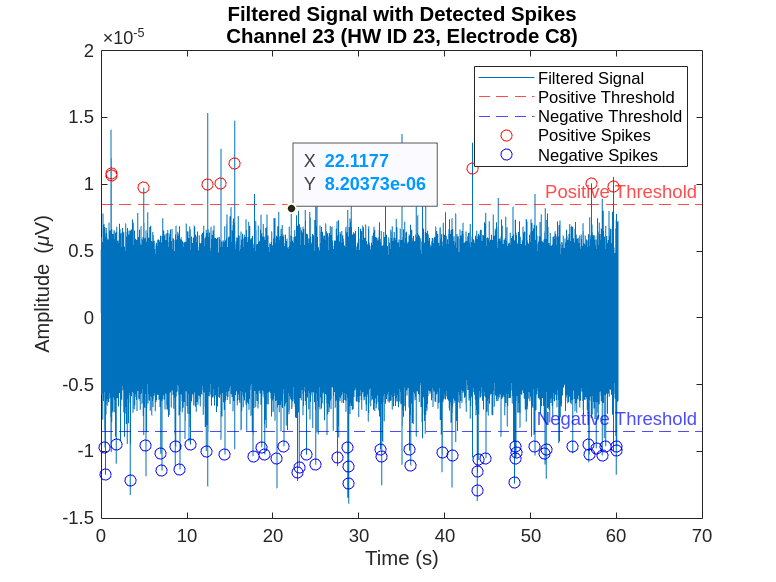

% Plot the filtered signal & thresholds
figure;
plot(timeVector, filteredData(:, channelIdx));
hold on;

yline(positiveThreshold, 'r--', 'Positive Threshold');
yline(negativeThreshold, 'b--', 'Negative Threshold');

% Overlay the detected spikes
if numSpikes > 0
    spikeIndices_ch = round(spikeTimes_ch * fs);
    % Ensure indices are within bounds
    spikeIndices_ch(spikeIndices_ch < 1) = 1;
    spikeIndices_ch(spikeIndices_ch > totalSamples) = totalSamples;
    
    % Plot all spikes
    positiveSpikes = spikeIndices_ch(spikePolarities_ch == 1);
    if ~isempty(positiveSpikes)
        plot(timeVector(positiveSpikes), filteredData(positiveSpikes, channelIdx), 'ro');
    end
    
    negativeSpikes = spikeIndices_ch(spikePolarities_ch == -1);
    if ~isempty(negativeSpikes)
        plot(timeVector(negativeSpikes), filteredData(negativeSpikes, channelIdx), 'bo');
    end
end

xlabel('Time (s)');
ylabel('Amplitude (\muV)');
title(sprintf('Filtered Signal with Detected Spikes\nChannel %d (HW ID %d, Electrode %s)', ...
    channelIdx, hw_id, electrodeLabel));
legend('Filtered Signal', 'Positive Threshold', 'Negative Threshold', 'Positive Spikes', 'Negative Spikes');

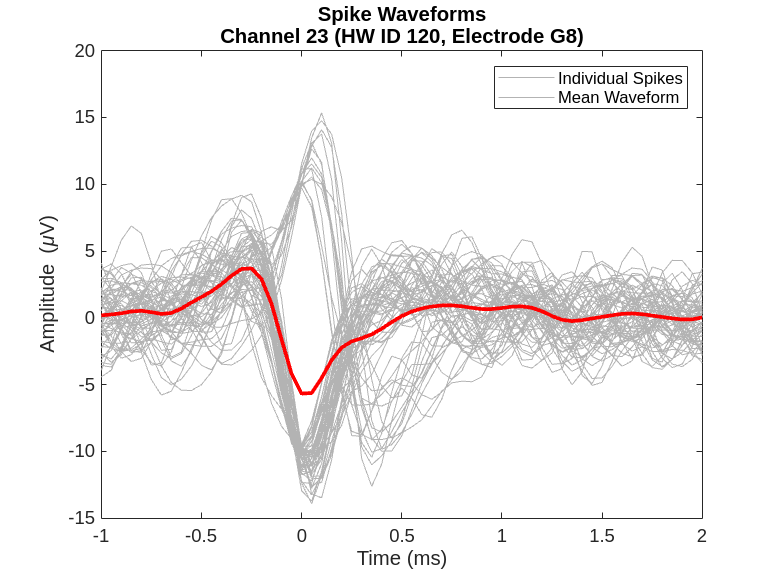

% Adjust preEvent and postEvent window sizes if necessary
preEventMs = 1;   % Pre-event time in ms (adjust if needed)
postEventMs = 2;  % Post-event time in ms

% Convert to samples
preEventSamples = round(preEventMs / 1000 * fs);
postEventSamples = round(postEventMs / 1000 * fs);

% Extract spike waveforms
waveforms = [];
for i = 1:length(spikeIndices_ch)
    idx = spikeIndices_ch(i);
    if idx > preEventSamples && idx + postEventSamples <= totalSamples
        waveforms(i, :) = filteredData(idx - preEventSamples : idx + postEventSamples, channelIdx);
    else
        waveforms(i, :) = NaN;  % Avoid out-of-bounds error
    end
end

% Time axis for plotting waveforms in milliseconds
waveformTime = (-preEventSamples : postEventSamples) / fs * 1000;  % Convert to ms

% Plot individual waveforms
figure;
plot(waveformTime, waveforms' * 1e6, 'Color', [0.7 0.7 0.7]);  % All waveforms (converted to microvolts)
hold on;

% Plot mean waveform
meanWaveform = mean(waveforms, 1, 'omitnan');
plot(waveformTime, meanWaveform * 1e6, 'r', 'LineWidth', 2);  % Mean waveform

% Add labels
xlabel('Time (ms)');
ylabel('Amplitude (\muV)');
title(sprintf('Spike Waveforms\nChannel %d (HW ID %d, Electrode %s)', ...
    channelIdx, hw_id, electrodeLabel));
legend('Individual Spikes', 'Mean Waveform');

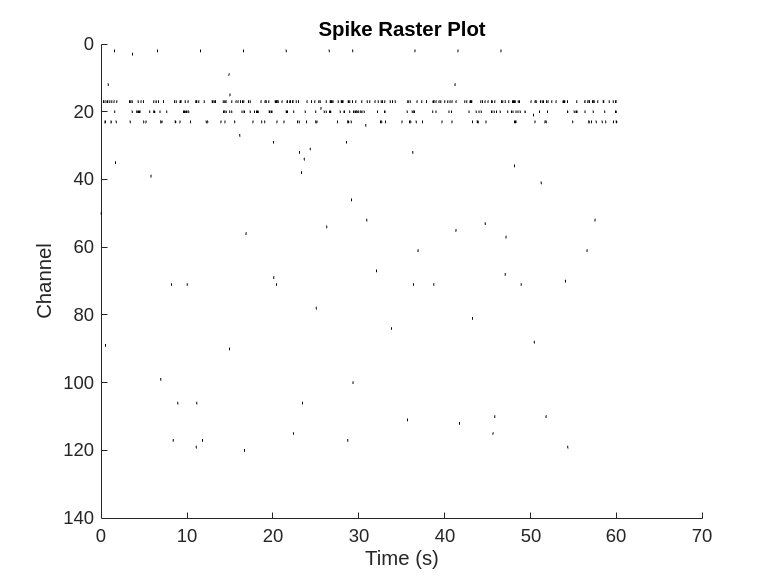

% Create a raster plot for spikes across all channels
figure;
hold on;
for ch = 1:numChannels
    spikeTimes_ch = spikeTimes{ch};  % Get spike times for channel
    if ~isempty(spikeTimes_ch)
        % Plot the spike times as vertical lines for each channel
        for spike = 1:length(spikeTimes_ch)
            line([spikeTimes_ch(spike), spikeTimes_ch(spike)], [ch-0.4, ch+0.4], 'Color', 'k');
        end
    end
end

xlabel('Time (s)');
ylabel('Channel');
title('Spike Raster Plot');
set(gca, 'YDir', 'reverse');  % Optional: Reverse the Y-axis so Channel 1 is on top


% Channel index for visualization
channelIdx = 23;  % Change as needed for other channels

% Get the adjusted hardware ID and electrode label
hw_id = infoChannel.ChannelID(channelIdx) + 1;  % one-based indexing
if isKey(hw_to_el_map, hw_id)
    electrodeLabel = hw_to_el_map(hw_id);
else
    electrodeLabel = 'Unknown';
end

fprintf('Visualizing spikes for Channel %d (HW ID %d, Electrode %s)\n', ...
    channelIdx, hw_id, electrodeLabel);

Visualizing spikes for Channel 23 (HW ID 23, Electrode C8)


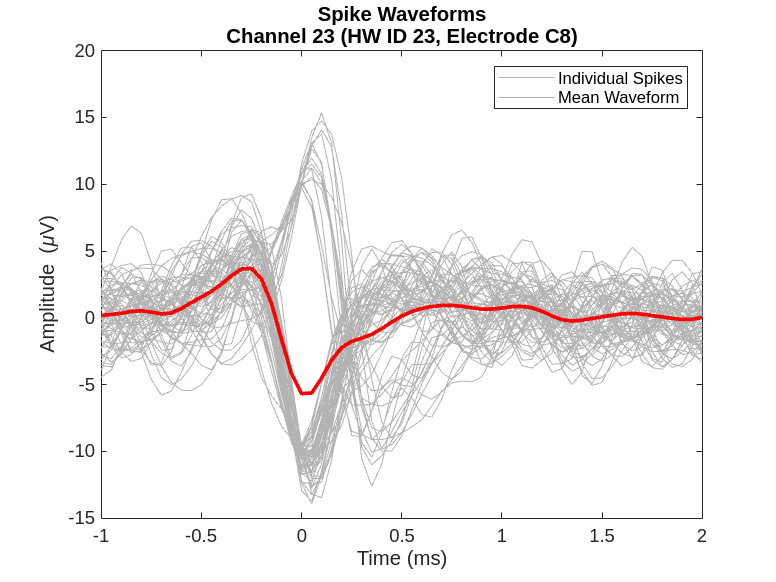


% Extract spike times, waveforms, and polarities for the selected channel
spikeTimes_ch = spikeTimes{channelIdx};
spikeWaveforms_ch = spikeWaveforms{channelIdx};

% Time axis for plotting waveforms in milliseconds
waveformTime = (-preEventSamples : postEventSamples) / fs * 1000;  % Convert to ms

% Plot individual waveforms
figure;
plot(waveformTime, spikeWaveforms_ch' * 1e6, 'Color', [0.7 0.7 0.7]);  % All waveforms (converted to microvolts)
hold on;

% Plot mean waveform
meanWaveform = mean(spikeWaveforms_ch, 1, 'omitnan');
plot(waveformTime, meanWaveform * 1e6, 'r', 'LineWidth', 2);  % Mean waveform

% Add labels
xlabel('Time (ms)');
ylabel('Amplitude (\muV)');
title(sprintf('Spike Waveforms\nChannel %d (HW ID %d, Electrode %s)', ...
    channelIdx, hw_id, electrodeLabel));
legend('Individual Spikes', 'Mean Waveform');

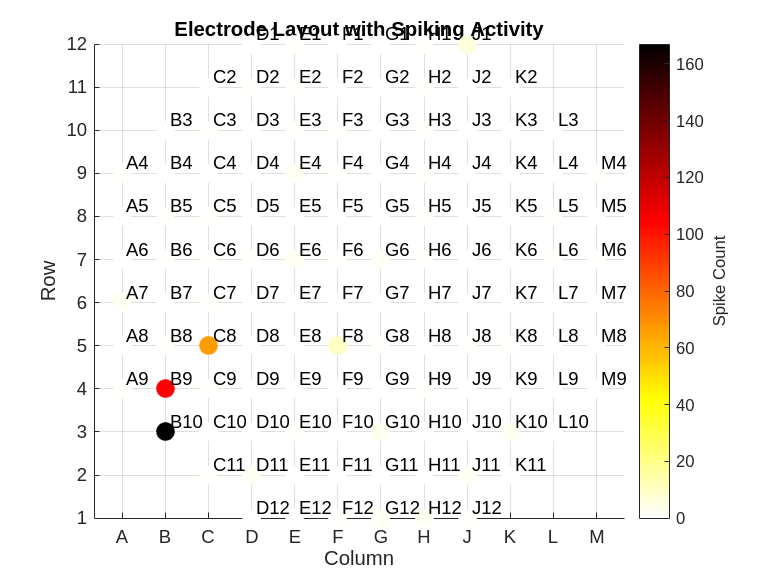

% Read the InfoChannel dataset
infoChannel = h5read(filename, infoPath);

% Extract the Channel IDs from the InfoChannel dataset
channelIDs = infoChannel.ChannelID;  % Hardware IDs from data (zero-based indexing)

% Adjust channelIDs to one-based indexing
channelIDs_one_based = channelIDs + 1;

% Define the hardware IDs and corresponding electrode IDs (one-based indexing)
hw_ids = [
    % First column from your table
    60, 59, 58, 57, 56, 55, 54, 53, 52, 51, 50, 49, 48, 47, 46, 45, 44, 43, 42, 41, 40, 39, 38, 37, 36, 35, 34, 33, 32, 31, ...
    % Second column
    120, 119, 118, 117, 116, 115, 114, 113, 112, 111, 110, 109, 108, 107, 106, 105, 104, 103, 102, 101, 100, 99, 98, 97, 96, 95, 94, 93, 92, 91, ...
    % Third column
    90, 89, 88, 87, 86, 85, 84, 83, 82, 81, 80, 79, 78, 77, 76, 75, 74, 73, 72, 71, 70, 69, 68, 67, 66, 65, 64, 63, 62, 61, ...
    % Fourth column
    30, 29, 28, 27, 26, 25, 24, 23, 22, 21, 20, 19, 18, 17, 16, 15, 14, 13, 12, 11, 10, 9, 8, 7, 6, 5, 4, 3, 2, 1
];

el_ids = {
    % First column EL IDs
    'F5', 'F1', 'F2', 'F3', 'F4', 'E1', 'E2', 'E3', 'E4', 'D1', 'D2', 'D3', 'E5', 'C2', 'C3', 'B3', 'D4', 'C4', 'B4', 'A4', 'D5', 'C5', 'B5', 'A5', 'D6', 'C6', 'B6', 'A6', 'E6', 'F6', ...
    % Second column EL IDs
    'G8', 'G12', 'G11', 'G10', 'G9', 'H12', 'H11', 'H10', 'H9', 'J12', 'J11', 'J10', 'H8', 'K11', 'K10', 'L10', 'J9', 'K9', 'L9', 'M9', 'J8', 'K8', 'L8', 'M8', 'J7', 'K7', 'L7', 'M7', 'H7', 'G7', ...
    % Third column EL IDs
    'H6', 'M6', 'L6', 'K6', 'J6', 'M5', 'L5', 'K5', 'J5', 'M4', 'L4', 'K4', 'H5', 'L3', 'K3', 'K2', 'J4', 'J3', 'J2', 'J1', 'H4', 'H3', 'H2', 'H1', 'G4', 'G3', 'G2', 'G1', 'G5', 'G6', ...
    % Fourth column EL IDs
    'E7', 'A7', 'B7', 'C7', 'D7', 'A8', 'B8', 'C8', 'D8', 'A9', 'B9', 'C9', 'E8', 'B10', 'C10', 'C11', 'D9', 'D10', 'D11', 'D12', 'E9', 'E10', 'E11', 'E12', 'F9', 'F10', 'F11', 'F12', 'F8', 'F7'
};

% Create a mapping between hardware IDs and electrode IDs 
hw_to_el_map = containers.Map(hw_ids, el_ids);

% Get the electrode names for the channels 
numChannels = length(channelIDs_one_based);
electrodeNames = cell(numChannels, 1);

for i = 1:numChannels
    hw_id = channelIDs_one_based(i);  % Hardware IDs adjusted to one-based indexing
    if isKey(hw_to_el_map, hw_id)
        electrodeNames{i} = hw_to_el_map(hw_id);
    else
        electrodeNames{i} = 'Unknown';
        warning(['Hardware ID ', num2str(hw_id), ' not found in mapping.']);
    end
end

% ---- Calculate Spike Counts ----

% Initialize spike count array for each channel
spikeCounts = zeros(numChannels, 1);

for ch = 1:numChannels
    % Get the spike times for the current channel
    spikeTimes_ch = spikeTimes{ch};
    
    % Count the number of spikes for the channel
    spikeCounts(ch) = length(spikeTimes_ch);
end

% ---- Incorporating Spike Counts into the Electrode Layout ----

% Initialize arrays to hold grid positions
X = zeros(numChannels, 1);  % Column indices
Y = zeros(numChannels, 1);  % Row indices

% Define the list of column letters in order
columnLetters = {'A', 'B', 'C', 'D', 'E', 'F', 'G', 'H', 'J', 'K', 'L', 'M', 'N', 'O', 'P'}; % can be adjusted for other MEAs
numColumns = length(columnLetters);
columnMap = containers.Map(columnLetters, 1:numColumns);
maxRowNumber = 12; 

for i = 1:numChannels
    electrode = electrodeNames{i};
    if strcmp(electrode, 'Unknown')
        % Skip unknown electrodes
        X(i) = NaN;
        Y(i) = NaN;
        continue;
    end
    % Find the index where the digits start
    idx = regexp(electrode, '\d');
    if isempty(idx)
        error(['No digits found in electrode name: ', electrode]);
    end
    colStr = electrode(1:idx(1)-1);  % Column letters
    rowStr = electrode(idx(1):end);  % Row number as string

    % Map column letters to numerical positions
    if isKey(columnMap, colStr)
        colNum = columnMap(colStr);
    else
        error(['Column letter ', colStr, ' not found in column mapping.']);
    end

    % Convert row string to numerical value
    rowNum = str2double(rowStr);
    if isnan(rowNum)
        error(['Invalid row number in electrode name: ', electrode]);
    end

    % Store the positions
    X(i) = colNum;
    Y(i) = rowNum;
end

% Adjust Y positions if necessary (e.g., flip Y-axis)
Y = maxRowNumber - Y + 1;

% Remove any electrodes with unknown positions
validIndices = ~isnan(X) & ~isnan(Y);
X_valid = X(validIndices);
Y_valid = Y(validIndices);
spikeCounts_valid = spikeCounts(validIndices);  % Filter the spike counts to match valid electrodes
electrodeNames_valid = electrodeNames(validIndices);

% ---- Visualization with Spike Counts ----

% Initialize a color map for the spike activity
figure;
scatter(X_valid, Y_valid, 100, spikeCounts_valid, 'filled');
text(X_valid + 0.1, Y_valid, electrodeNames_valid, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
colormap('hot');colormap(flipud(hot));  % Flip the 'hot' color map
c = colorbar;
ylabel(c, 'Spike Count');

% Add labels and grid
xlabel('Column');
ylabel('Row');
title('Electrode Layout with Spiking Activity');
axis equal;
set(gca, 'YDir', 'normal');  % Adjust to 'reverse' if necessary
xticks(1:numColumns);
xticklabels(columnLetters);
yticks(1:maxRowNumber);
grid on;

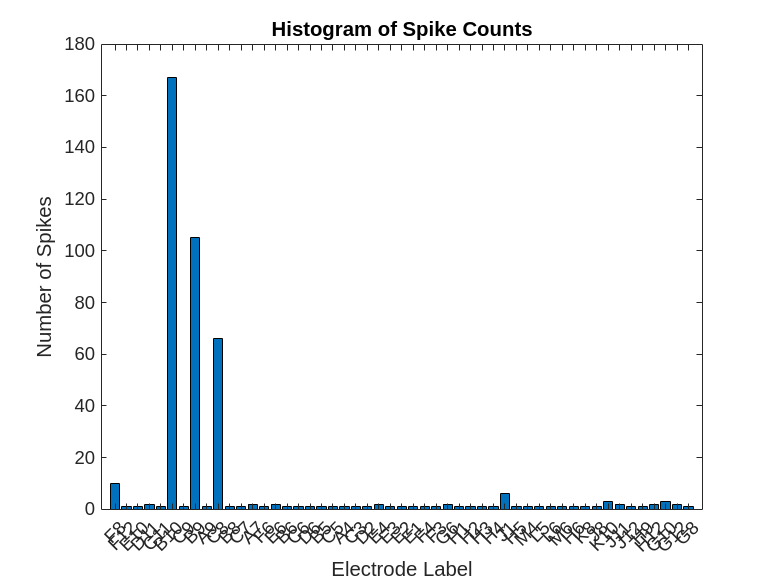

% Find channels with more than 0 spikes
nonZeroSpikeIndices = spikeCounts > 0;
nonZeroSpikeCounts = spikeCounts(nonZeroSpikeIndices);
nonZeroElectrodeLabels = electrodeNames_valid(nonZeroSpikeIndices);

% Create the histogram
figure;
bar(nonZeroSpikeCounts);

% Add labels to the x-axis
set(gca, 'XTick', 1:length(nonZeroElectrodeLabels), 'XTickLabel', nonZeroElectrodeLabels);
xtickangle(45);  % Rotate the labels for better visibility

% Add labels and title
xlabel('Electrode Label');
ylabel('Number of Spikes');
title('Histogram of Spike Counts');